clear;

data = load("\\wsl.localhost\Ubuntu\home\merlijn\projects\brain_computer_project\Ass2\BI5_segments_HTS.mat")

data = struct with fields:
    ch_selection: {'Fz'  'Cz'  'Pz'}
              fs: 64
     classlabels: [2200×1 double]
        segments: [3×77×2200 double]
               t: [0 0.0156 0.0312 0.0469 0.0625 0.0781 0.0938 0.1094 0.1250 0.1406 0.1562 0.1719 0.1875 0.2031 0.2188 0.2344 0.2500 0.2656 0.2812 0.2969 0.3125 0.3281 0.3438 0.3594 0.3750 0.3906 0.4062 0.4219 0.4375 0.4531 0.4688 0.4844 … ] (1×77 double)


segments = data.segments;
labels = data.classlabels;
t = data.t;
channels = data.ch_selection;

non_target_idx = find(labels == 1);
target_idx = find(labels == 2);

non_tar =  data.segments(:, :, non_target_idx);
tar = data.segments(:, :, target_idx);

% Fz
% signal over all trials + mean over trials that we need for later
Fz_non_tar = non_tar(1, :, :);
Fz_tar = tar(1, :, :);
Fz_mean_non_tar = mean(non_tar(1, :, :), 3);
Fz_mean_tar = mean(tar(1, :, :), 3);

%Cz
Cz_non_tar = non_tar(2, :, :);
Cz_tar = tar(2, :, :);
Cz_mean_non_tar = mean(non_tar(2, :, :), 3);
Cz_mean_tar = mean(tar(2, :, :), 3);

%Pz
Pz_non_tar = non_tar(3, :, :);
Pz_tar = tar(3, :, :);
Pz_mean_non_tar = mean(non_tar(3, :, :), 3);
Pz_mean_tar = mean(tar(3, :, :), 3);

% this function performs the Wilcoxon test (for each timestep, across all
% the trials) between target and non-target group. It uses the Bonferroni
% correction
function diff = stat_diff(tar, non_tar)
    num_timesteps = size(tar, 2);
    diff = zeros(num_timesteps, 1);

    for i = 1:num_timesteps
        time_tar = tar(:, i, :);
        time_non = non_tar(:, i, :);
        
        [~, h] = ranksum(time_tar(:), time_non(:), 'alpha', (0.01/num_timesteps)); %Bonferroni correction
        
        % we store a list that has a 1 if a timestep was significantly
        % differena and 0 if it was not
        diff(i) = h;
    end
end

% we compute the statistics for each channel
Fz_stats = stat_diff(Fz_tar, Fz_non_tar);
Cz_stats = stat_diff(Cz_tar, Cz_non_tar);
Pz_stats = stat_diff(Pz_tar, Pz_non_tar);

% statistical significance of the difference between target and non-target
% for each time point

% Fz
% this is timestep 1
% time_2_tar = Fz_tar(:,2,:);
% time_2_non = Fz_non_tar(:,2,:);
% 
% % use (:) to flatten the matrix into a vector because ranksum wants it
% ranksum(time_2_tar(:), time_2_non(:));
% 
% 
% % num_timesteps = size(Fz_tar, 2);
% % results = zeros(num_timesteps, 1);
% 
% for i = 1:num_timesteps
%     % disp('hello')
%     time_tar = Fz_tar(:,i,:);
%     time_non = Fz_non_tar(:, i, :);
%     [p, h] = ranksum(time_tar(:), time_non(:), 'alpha', (0.01/num_timesteps)); % Bonferroni
%     results(i) = h;
% end
% 
% results;

% we combine the statistical information with the actual time in seconds
% for the plot. Every time the statistical significance is 1, we pick the
% corresponding time and plot a line to visualize it
% 
% timeline = [Fz_stats'; t];
% timeline(2, 3);
% for i = 1:length(timeline)
%     if timeline(1,i) == 1
%         disp(timeline(2, i))
%     end
% end

% this function plots a line where a timestep is significant
function plot_stats(stats, t)
    % whenever the stats are 1 (significant), we take that specific time,
    % measured in seconds, so it can be plotted
    sig_times = t(stats == 1);
    
    if ~isempty(sig_times)
        xline(sig_times, 'Color', [0.8 0.8 0.8], 'HandleVisibility', 'off');
    end
end

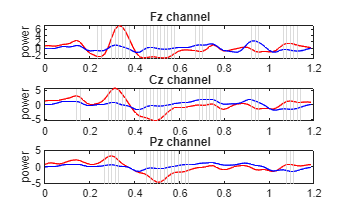

figure;
%Fz
subplot(3, 1, 1);
plot(t, Fz_mean_tar, 'r');
hold on
plot(t, Fz_mean_non_tar, 'b');
hold on
plot_stats(Fz_stats, t)
hold off
title('Fz channel')
ylabel('power')

%Cz
subplot(3, 1, 2);
plot(t, Cz_mean_tar, 'r');
hold on
plot(t, Cz_mean_non_tar, 'b');
hold on
plot_stats(Cz_stats, t)
hold off
title('Cz channel')
ylabel('power')

%Pz
subplot(3, 1, 3);
plot(t, Pz_mean_tar, 'r');
hold on
plot(t, Pz_mean_non_tar, 'b');
hold on
plot_stats(Pz_stats, t)
hold off
title('Pz channel')
ylabel('power')